clear;clc;

## 读取数据

load("PointOctahedron.mat")
P_bound1 = top_face_transformed(10,:);
P_bound2 = bottom_face_transformed(20,:);
planes = planes';




PAB = [-0.176,-0.06,0.6]';
% P_bound1 = [-0.142,0.47,0.061]*2;
% P_bound2 = [0.57,-0.48,0.138];
phi = pi./4;
phi = pi./2 - phi;
shenglunum = 6;
a = 0.015*ones(1,2*shenglunum);
distanceThreshold = 0.2;


[PlaneParaOut8,TrianglePoints8,MaxDis,distancesFianal] = planefit8(side_faces_transformed1',side_faces_transformed2',side_faces_transformed3',side_faces_transformed4',side_faces_transformed5',side_faces_transformed6',side_faces_transformed7',side_faces_transformed8',P_bound1,P_bound2,0.2);

Isempty FACE2468: 100.000000, 100.000000, 100.000000, 100.000000


## 计算 AB面

% 加 输出   计算 和判断 偏移
Ti = ShengDaoGaoDu(shenglunum);

[PointTable_A_off8,PointTable_B_off8,XieMianPianYi] = Calculate_rectangle_from_vertex8(side_faces_transformed1',side_faces_transformed2',side_faces_transformed3',side_faces_transformed4',side_faces_transformed5',side_faces_transformed6',side_faces_transformed7',side_faces_transformed8',P_bound1,P_bound2,PAB,phi,shenglunum,Ti,a,distanceThreshold)

Isempty FACE2468: 100.000000, 100.000000, 100.000000, 100.000000


PointTable_A_off8 =     0.5763    0.5526   -0.0922   -0.2680    0.0743   -0.1021   -0.3772   -0.3531    0.2925    0.4682    0.1263    0.3028
   -0.3363   -0.2447   -0.3087   -0.1923    0.0730    0.1137    0.0219   -0.0696   -0.0053   -0.1217   -0.3869   -0.4276
    0.6916    0.8846   -0.0592    0.0082    1.0699    0.9528    0.3938    0.2016    1.1469    1.0796    0.0186    0.1359


PointTable_B_off8 =     0.3035    0.1275    0.4682    0.2925   -0.3535   -0.3775   -0.1019    0.0745   -0.2680   -0.0922    0.5532    0.5767
   -0.6442   -0.7248    0.3250    0.4414   -0.4109   -0.1984    0.3327    0.4140   -0.6390   -0.7554    0.0959   -0.1176
    0.5122    0.6056    0.3075    0.3748    0.7906    0.7740    0.5746    0.4810    0.7803    0.7129    0.2976    0.3146


XieMianPianYi =     0.0150    0.0150         0         0    0.0149    0.0149    0.0150    0.0150         0         0    0.0150    0.0150


## 验证

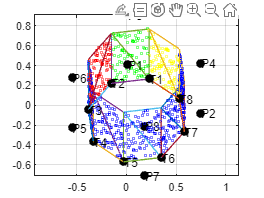

figure
hold on 
box on
grid on
axis equal
scatter3(side_faces_transformed1(:,1),side_faces_transformed1(:,2),side_faces_transformed1(:,3),5,'yellow')
scatter3(side_faces_transformed2(:,1),side_faces_transformed2(:,2),side_faces_transformed2(:,3),5,'green')
scatter3(side_faces_transformed3(:,1),side_faces_transformed3(:,2),side_faces_transformed3(:,3),5,'red')
scatter3(side_faces_transformed4(:,1),side_faces_transformed4(:,2),side_faces_transformed4(:,3),5,'blue')
scatter3(side_faces_transformed5(:,1),side_faces_transformed5(:,2),side_faces_transformed5(:,3),5,'blue')
scatter3(side_faces_transformed6(:,1),side_faces_transformed6(:,2),side_faces_transformed6(:,3),5,'blue')
scatter3(side_faces_transformed7(:,1),side_faces_transformed7(:,2),side_faces_transformed7(:,3),5,'blue')
scatter3(side_faces_transformed8(:,1),side_faces_transformed8(:,2),side_faces_transformed8(:,3),5,'blue')
for i =1:16
    idt = [(i-1)*3+1:i*3,(i-1)*3+1];
    PointTri = TrianglePoints8(:,idt);
    plot3(PointTri(1,:),PointTri(2,:),PointTri(3,:));
end
% 
% scatter3(PointTable_A_off8(1,:),PointTable_A_off8(2,:),PointTable_A_off8(3,:),50,'filled','black')
% scatter3(PointTable_B_off8(1,:),PointTable_B_off8(2,:),PointTable_B_off8(3,:),50,'filled','black')

PP4 = TrianglePoints8(:,[1,8,14,20,26,32,38,2]);
scatter3(PP4(1,1),PP4(2,1),PP4(3,1),50,'filled','black')
scatter3(PP4(1,2),PP4(2,2),PP4(3,2),50,'filled','black')
scatter3(PP4(1,3),PP4(2,3),PP4(3,3),50,'filled','black')
scatter3(PP4(1,4),PP4(2,4),PP4(3,4),50,'filled','black')
scatter3(PP4(1,5),PP4(2,5),PP4(3,5),50,'filled','black')
scatter3(PP4(1,6),PP4(2,6),PP4(3,6),50,'filled','black')
scatter3(PP4(1,7),PP4(2,7),PP4(3,7),50,'filled','black')
scatter3(PP4(1,8),PP4(2,8),PP4(3,8),50,'filled','black')
text(PP4(1,1),PP4(2,1),PP4(3,1),'T1')
text(PP4(1,2),PP4(2,2),PP4(3,2),'T2')
text(PP4(1,3),PP4(2,3),PP4(3,3),'T3')
text(PP4(1,4),PP4(2,4),PP4(3,4),'T4')
text(PP4(1,5),PP4(2,5),PP4(3,5),'T5')
text(PP4(1,6),PP4(2,6),PP4(3,6),'T6')
text(PP4(1,7),PP4(2,7),PP4(3,7),'T7')
text(PP4(1,8),PP4(2,8),PP4(3,8),'T8')



[~,TrianglePoints4,~,~] = planefit4(side_faces_transformed1',side_faces_transformed3',side_faces_transformed5',side_faces_transformed7',P_bound1,P_bound2,0.2);
PP5 = TrianglePoints4(:,[1,2,3,6,9,12,15,18]);


scatter3(PP5(1,1),PP5(2,1),PP5(3,1),50,'filled','black')
scatter3(PP5(1,2),PP5(2,2),PP5(3,2),50,'filled','black')
scatter3(PP5(1,3),PP5(2,3),PP5(3,3),50,'filled','black')
scatter3(PP5(1,4),PP5(2,4),PP5(3,4),50,'filled','black')
scatter3(PP5(1,5),PP5(2,5),PP5(3,5),50,'filled','black')
scatter3(PP5(1,6),PP5(2,6),PP5(3,6),50,'filled','black')
scatter3(PP5(1,7),PP5(2,7),PP5(3,7),50,'filled','black')
scatter3(PP5(1,8),PP5(2,8),PP5(3,8),50,'filled','black')
text(PP5(1,1),PP5(2,1),PP5(3,1),'P1')
text(PP5(1,2),PP5(2,2),PP5(3,2),'P2')
text(PP5(1,3),PP5(2,3),PP5(3,3),'P3')
text(PP5(1,4),PP5(2,4),PP5(3,4),'P4')
text(PP5(1,5),PP5(2,5),PP5(3,5),'P5')
text(PP5(1,6),PP5(2,6),PP5(3,6),'P6')
text(PP5(1,7),PP5(2,7),PP5(3,7),'P7')
text(PP5(1,8),PP5(2,8),PP5(3,8),'P8')